Question 2:

This image is clearly corrupted by additive sinusoidal noise. A similar example is found in the textbook in Figure 5.5. The picture I have been given has two sinusoids.

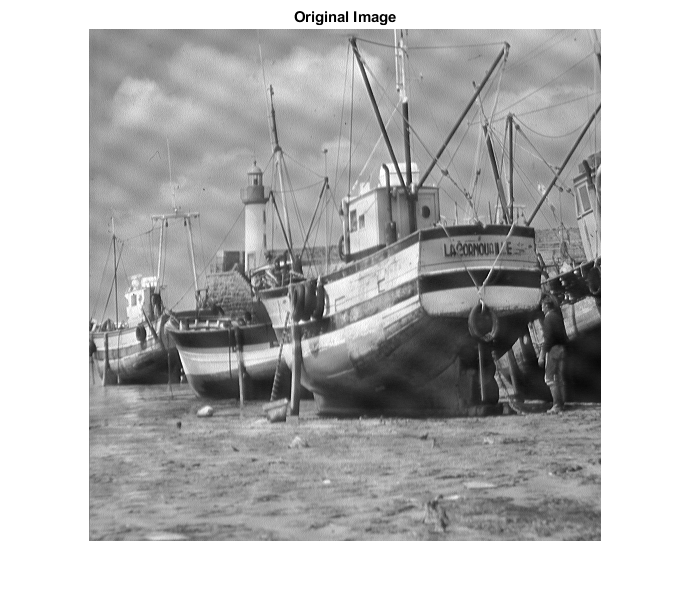

f = imread("ExamFig5proc.png");
imshow(f);
title('Original Image');

To eliminate the corruption, start by viewing the image in its magnitude spectrum. This is done with the two-dimensional Fast Fourier Transform and then shifted to the center.

% Fourier Transform
F = fft2(f);

% Shift
F_s = fftshift(F);

The magnitude is the absolute value of the transformed image. To easily view the spectrum, the output needs to be scaled to magnify the differences.

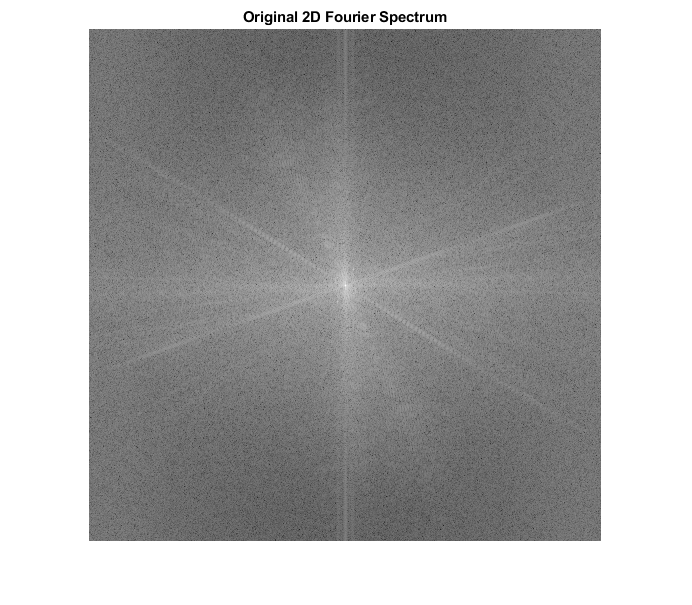

% show spectrum before
magnitude = abs(F_s);
mag_scaled = uint8(15 * log(1 + magnitude));
imshow(mag_scaled);
title('Original 2D Fourier Spectrum');

Two pairs of points can be found in the spectrum. These are the sources of the corruption. To eliminate these points, a notch filter will be created with notches at the specified points.

% create notch filter
filt = ones(512, 512);
r = 2;
filt = filter_radius(273, 249, r, filt);
filt = filter_radius(241, 265, r, filt);
filt = filter_radius(249, 249, r, filt);
filt = filter_radius(265, 265, r, filt);

% apply filter
F_s_f = F_s .* filt;

The reulting spectrum clearly shows four black spots where the noise has been eliminated.

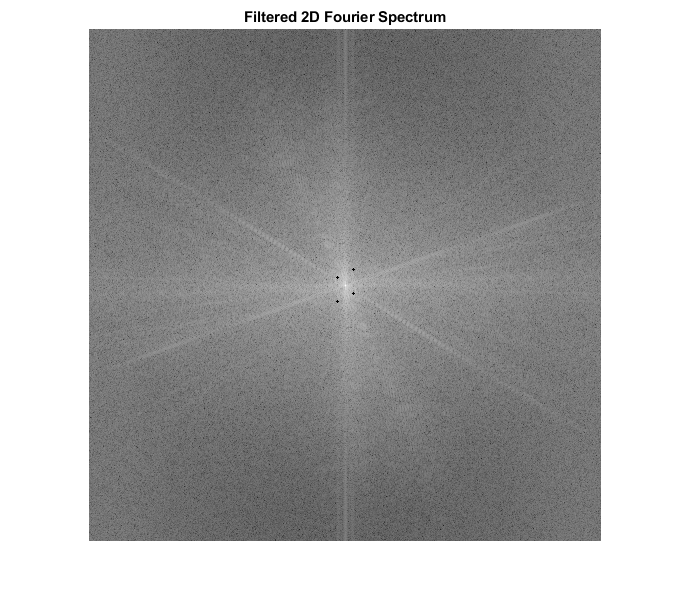

% show spectrum after
magnitude = abs(F_s_f);
mag_scaled = uint8(15 * log(1 + magnitude));
imshow(mag_scaled);
title('Filtered 2D Fourier Spectrum');

Now that the corruption is removed, convert the image back to the image domain. This is done be inverting the shift and inverting the Transform.

% Inverse shift
F_f = ifftshift(F_s_f);

% Inverse Fourier Transform
f_f = ifft2(F_f);

% Convert back to uint8
f_f = uint8(real(f_f));

The image shown has greatly reduced corruption.

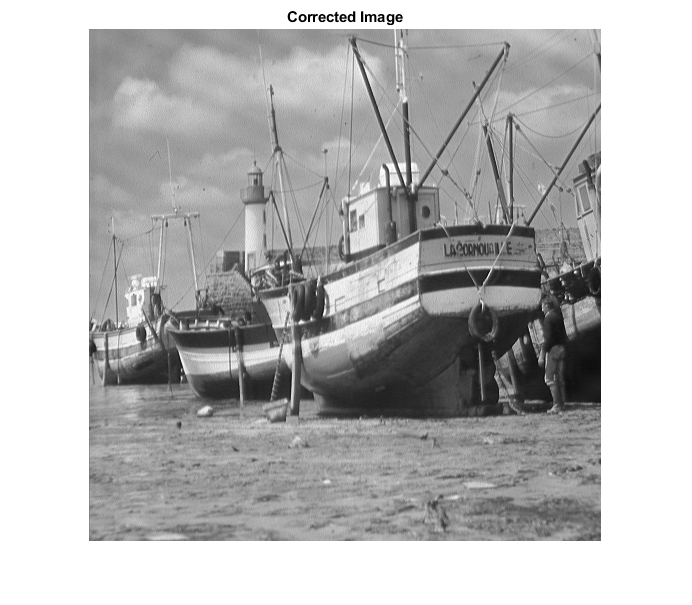

% Show corrected image
imshow(f_f);
title('Corrected Image')

The extraced noise can be seen by subtracted the before and after images.

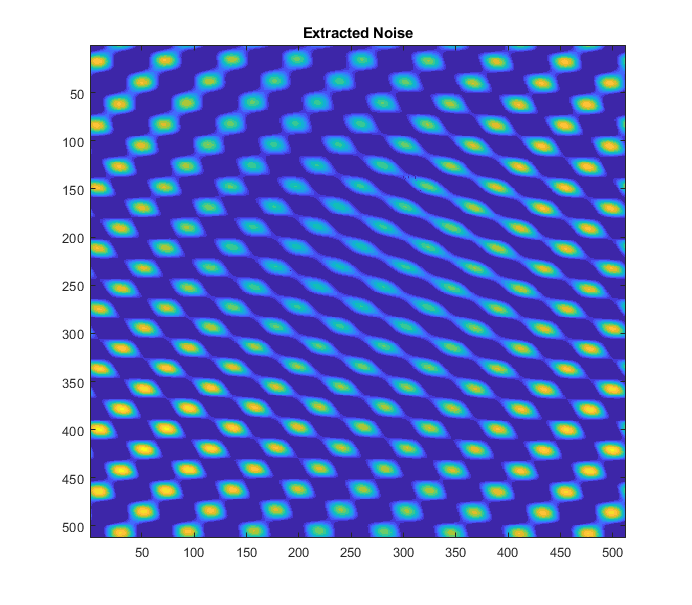

% Extract noise
imagesc(f_f - f);
title('Extracted Noise')

This is the image before the corruption. This image is compared to the filtered image to show its effectiveness.

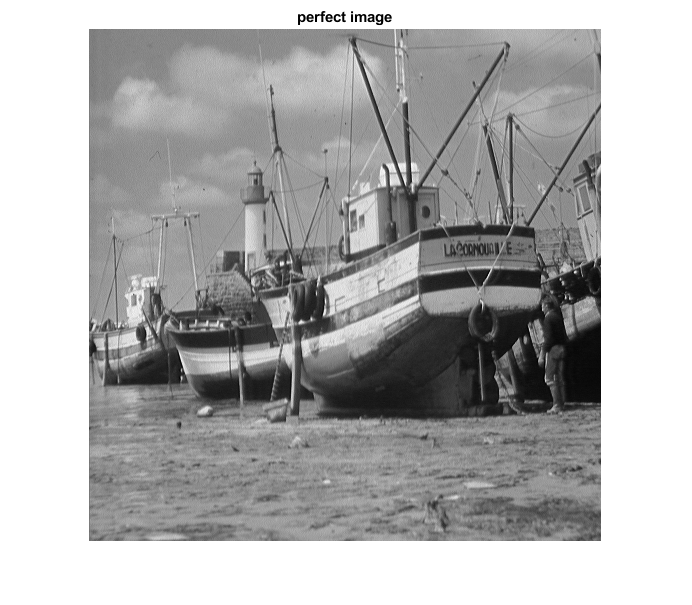

g = imread("ExamFig5orig.tiff");
imshow(g);
title('perfect image')

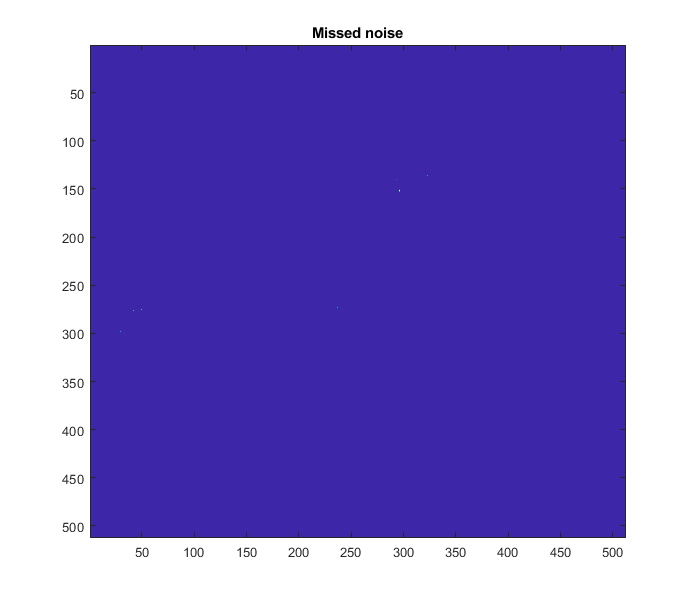


imagesc(abs(g - f_f));
title('Missed noise')

This is the function I designed to eliminate the noise in the shape '+'. This more accuratly masks the high frequency noise.

function filt = filter_radius(x, y, r, filt)
    for i = -r/2:r/2
        filt(x + i, y) = 0;
    end
    for j = -r/2:r/2
        filt(x, y + j) = 0;
    end
end